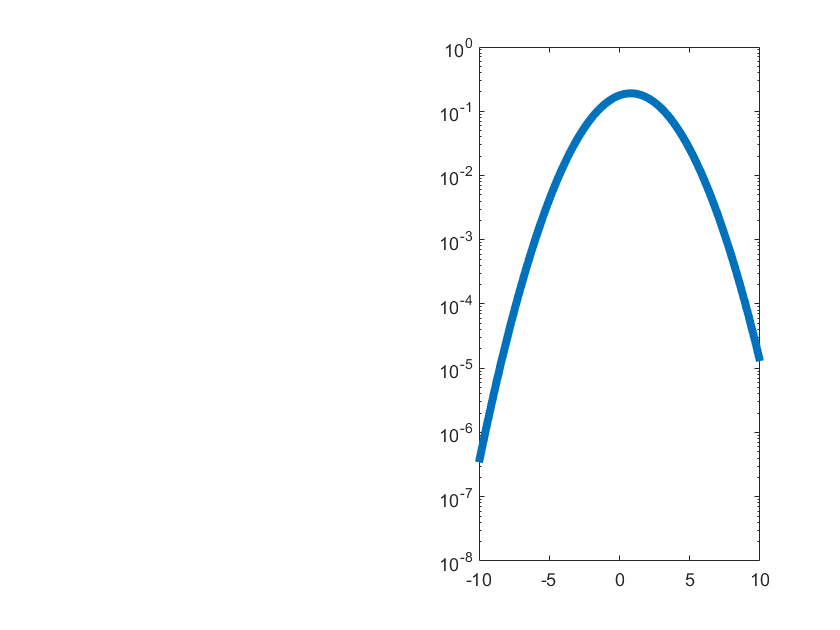

x = linspace(-10,10,1000);
gaus = makedist("Normal",'mu',0.8,'sigma',2.1); 
subplot(1,2,2)
plot(x,pdf(gaus,x),"LineWidth",4);
set(gca,'YScale','log')
ylim([1e-8,1])
xlim([-10,10])


normcdf(0, 0, 2) 

ans = 0.5000

normcdf(0, 3, 2)

ans = 0.0668

normcdf(0, 0, 7)

ans = 0.5000

normcdf(0, 0, 15)

ans = 0.5000

normcdf(1, 0, 2)

ans = 0.6915

normcdf(1, 0, 7)

ans = 0.5568

normcdf(1, 0, 9)

ans = 0.5442

norminv(0, 0, 2)

ans = -Inf

norminv(1, 0, 9)

ans = Inf

norminv(0, 3, 2)

ans = -Inf

normcdf(1, 2, 5)

ans = 0.4207

norminv(1, 2, 5)

ans = Inf

norminv(0.88)

ans = 1.1750

norminv(0.02)

ans = -2.0537

norminv(0.07)

ans = -1.4758

norminv(0.5)

ans = 0

% the - sign appears on sigma when the probability becomes greater than 1/2


x = linspace(0,100,100000)

x =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


Ray = makedist("Rayleigh", "b", 2.5)

Ray =   RayleighDistribution

  Rayleigh distribution
    B = 2.5


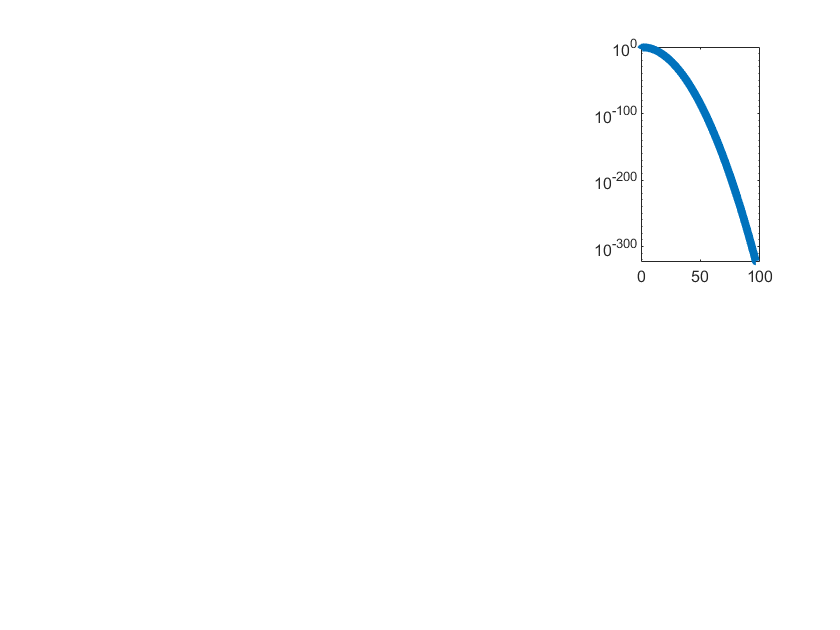

subplot(2,4,4)
plot(x,pdf(Ray,x),"Linewidth", 4)
set(gca,'Yscale','Log')

%What is the chance that data without a signal will produce a signal 
%that is equally or more signal-like than the one I received?
%That is, if I'm expecting an observation between 1 and 2?
raylcdf(1,2)

ans = 0.1175

erfcinv(0.1175)

ans = 1.1069

x = 0:10;
poisson = makedist("Poisson","lambda",2.5)

poisson =   PoissonDistribution

  Poisson distribution
    lambda = 2.5


subplot(1,2,2)
stairs(x-0.5,pdf(poisson,x),"Linewidth",4)


poisson2 = makedist("Poisson","lambda",4)

poisson2 =   PoissonDistribution

  Poisson distribution
    lambda = 4


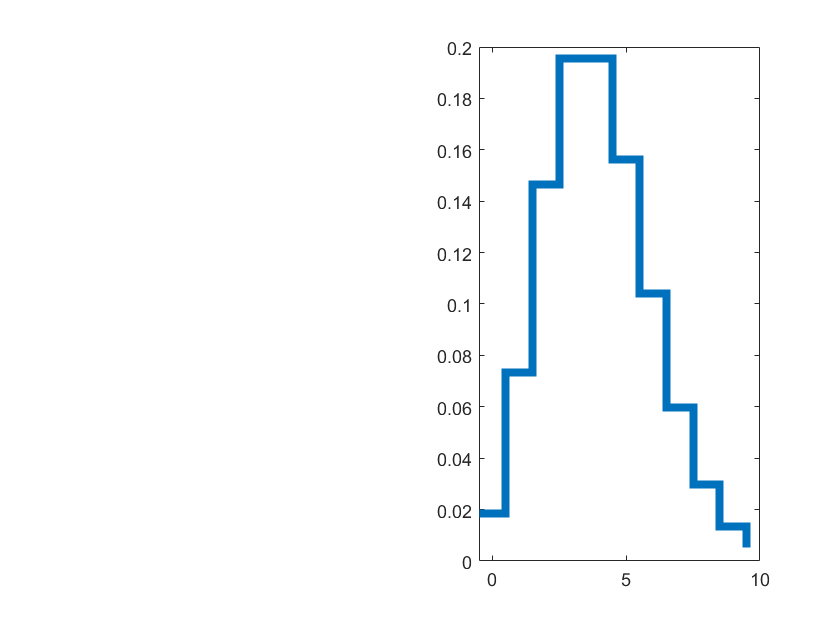

subplot(1,2,2)
stairs(x-0.5,pdf(poisson2,x),"Linewidth",4)

%The first two integrals are calculations of the probability of getting the
%expected value, and the last integral is a measure of the chance
%data with no signal will look as or more signal-like than our data when we
%receive a signal. 
cdf(poisson,4)

ans = 0.8912

poisscdf(4,2.5)

ans = 0.8912

erfcinv(0.8912)

ans = 0.0967